# POST-PROCESSING OF IMAGES FROM PLANAR KIRIGAMI EXPERIMENTS

"Continuum Field Theory for the Deformations of Planar Kirigami" Yue Zheng, Imtiar Niloy, Paolo Celli, Ian Tobasco, and Paul Plucinsky Phys. Rev. Lett. 128, 208003 ? Published 20 May 2022

% Code created on July 2021

close all;
clear all;
clc;

## INPUT NEEDED -- CHOICE OF SPECIMEN/EXPERIMENTAL RESULT TO ANALYZE

%filename='061521_AnIsoLRSidesCenterPull_v2_7cm'; para = [3 100]; % for Hyperbolic Pulling

filename='060821_IsoLRSidesCenterPull_8cm'; para = [0 42]; % for Elliptic Pulling
%filename='060821_IsoLRSidesCenterPull_0cm'; para = [0 42]; % for Elliptic Pulling

% filename = '070121_ForcedIntoAnnulus_Hyperbolic'; para = [0 42]; % for Hyperbolic Annulus

% filename = '070121_ForcedIntoAnnulus_Elliptic'; para = [0 42]; % for Elliptic Annulus

%filename = '063021_Mixed_LRSidesCenterPull_6'; para = [0 100]; %Test for mixed

## IMAGE READ

I = imread([filename,'.tif']);

BW = imbinarize(I);
BW = logical(1 - BW);

stats = regionprops('table',BW,'Centroid','Area','MajorAxisLength','MinorAxisLength','Orientation');
Cent = stats.Centroid;
Area = stats.Area;
Maax = stats.MajorAxisLength;
Miax = stats.MinorAxisLength;
Orit = stats.Orientation;
Orit = -Orit/180*pi;

hinge = para(1);
Maax = Maax + hinge;
Maax(Maax>para(2))=para(2);

Angle=atan(Miax./Maax);
%xi_in = 0.32 %0.219; %For mixed kirigami
%xi_in = 0.06; %0.06; %For hyperbolic kirigami
xi_in = 0.11; %0.09; %For auxetic kirigami
Angle = Angle-xi_in;

## INPUT NEEDED -- CHOOSE SLIT THRESHOLDS

%Slit=(Area>20 & Area<1000); % for Hyperbolic Pulling

Slit=(Area>20 & Area<3200); % for Elliptic Pulling

% Slit=(Area>20 & Area<1000); % for Hyperbolic Annulus

% Slit=(Area>20 & Area<2000); % for Elliptic Annulus

%Slit=(Area>200 & Area<1700) & Maax < 60;% for Mixed Pulling

## PLOTS

disp(Cent(Slit,1))

   1.0e+03 *

    0.1096
    0.1128
    0.1222
    0.1239
    0.1393
    0.1311
    0.1315
    0.1394
    0.1542
    0.1532
    0.1457
    0.1463
    0.1692
    0.1684
    0.1606
    0.1614
    0.1791
    0.1838
    0.1760
    0.1809
    0.1844
    0.1986
    0.1761
    0.2004
    0.1765
    0.1959
    0.1875
    0.1888
    0.1960
    0.2073
    0.2100
    0.2160
    0.2099
    0.2029
    0.2030
    0.1925
    0.1913
    0.2232
    0.2230
    0.2162
    0.2168
    0.2038
    0.2363
    0.2365
    0.2082
    0.2111
    0.2489
    0.2455
    0.2506
    0.2299
    0.2299
    0.2219
    0.2583
    0.2535
    0.2468
    0.2478
    0.2545
    0.2643
    0.2633
    0.2437
    0.2429
    0.2666
    0.2671
    0.2741
    0.2598
    0.2602
    0.2790
    0.2793
    0.2541
    0.2572
    0.2906
    0.2726
    0.2727
    0.2916
    0.2619
    0.3011
    0.2689
    0.3033
    0.2851
    0.2846
    0.3100
    0.3151
    0.3171
    0.3145
    0.3151
    0.2959
    0.2972
    0.3244
    0.3122
    0.3

disp(Cent(Slit,2))

   1.0e+03 *

    0.9899
    1.1200
    0.9232
    1.1873
    0.7935
    0.8571
    1.2532
    1.3177
    0.6664
    1.4457
    1.3825
    0.7285
    0.5433
    1.5711
    1.5095
    0.6035
    0.9912
    0.4246
    1.0544
    1.1188
    1.6927
    0.3114
    1.6332
    1.8094
    0.4826
    0.8615
    0.9258
    1.1843
    1.2486
    0.2033
    0.7338
    1.9198
    1.3770
    1.3137
    0.7966
    1.7523
    0.3664
    0.6092
    1.5029
    1.4409
    0.6705
    0.2559
    0.4888
    1.6258
    1.8664
    0.1497
    0.3726
    1.0554
    1.7447
    1.5654
    0.5477
    1.9714
    0.2611
    0.9274
    0.9907
    1.1191
    1.1837
    0.1539
    1.8588
    1.6860
    0.4295
    0.7998
    1.3116
    1.9681
    0.8625
    1.2482
    0.6744
    1.4378
    0.3158
    1.8022
    0.5524
    1.3755
    0.7357
    1.5612
    0.2066
    0.4340
    1.9127
    1.6814
    1.5002
    0.6122
    0.3193
    1.7979
    0.2086
    0.9917
    1.1195
    0.4923
    1.6218
    1.9097
    1.0552
    0.8

disp(Angle(Slit))

    0.7351
    0.7265
    0.7358
    0.7423
    0.6884
    0.6993
    0.7128
    0.7021
    0.6040
    0.6500
    0.6725
    0.6288
    0.5135
    0.5774
    0.6116
    0.5478
    0.7305
    0.4016
    0.7886
    0.7210
    0.4695
    0.2677
    0.5249
    0.3371
    0.4549
    0.6904
    0.6968
    0.7016
    0.7010
    0.1724
    0.6236
    0.1946
    0.6503
    0.6694
    0.6496
    0.3971
    0.3239
    0.5438
    0.5915
    0.6126
    0.5757
    0.1909
    0.4507
    0.5076
    0.2617
    0.1369
    0.3457
    0.7321
    0.3948
    0.5448
    0.4891
    0.1116
    0.2428
    0.6890
    0.7310
    0.7244
    0.6927
    0.1558
    0.2775
    0.4536
    0.3872
    0.6350
    0.6482
    0.1619
    0.6532
    0.6667
    0.5563
    0.5877
    0.2793
    0.3371
    0.4824
    0.6133
    0.5844
    0.5228
    0.1954
    0.3939
    0.2127
    0.4408
    0.5486
    0.5102
    0.3027
    0.3414
    0.2176
    0.6975
    0.7016
    0.4233
    0.4723
    0.2382
    0.7222
    0.6382
    0.6543

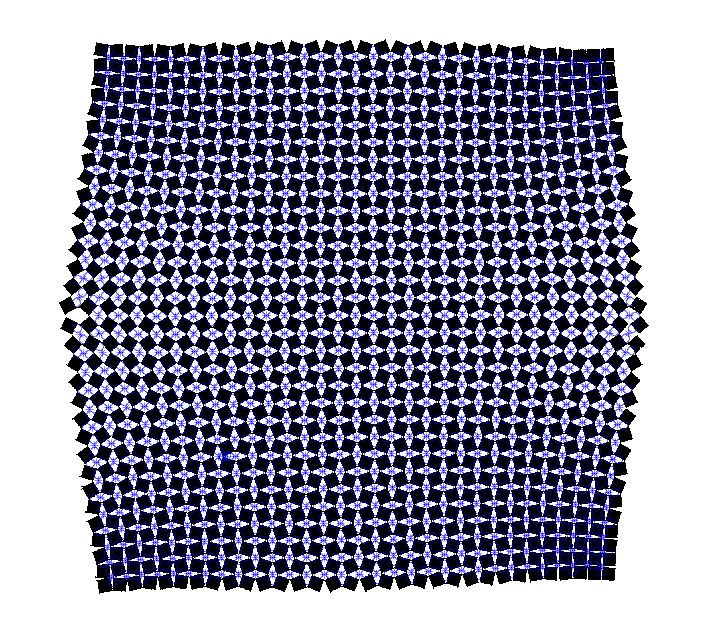


figure;
imshow(BW);
hold on;
plot(Cent(Slit,1),Cent(Slit,2),'b*')

plot([Cent(Slit,1)+Maax(Slit)/2.*cos(Orit(Slit)) Cent(Slit,1)-Maax(Slit)/2.*cos(Orit(Slit))]...
    ,[Cent(Slit,2)+Maax(Slit)/2.*sin(Orit(Slit)) Cent(Slit,2)-Maax(Slit)/2.*sin(Orit(Slit))],'bo')



figure;
subimage(BW);
hold on;
scatter2 = scatter(Cent(Slit,1),Cent(Slit,2),100,Angle(Slit),'filled')

scatter2 =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'none'
    MarkerFaceColor: 'flat'
          LineWidth: 0.5000
              XData: [109.6204 112.8234 122.1531 123.9155 139.3393 131.1420 131.5144 139.3600 154.1896 153.2466 145.6960 146.3295 169.2474 168.4429 160.5625 161.3830 179.1027 183.8049 176.0192 180.8835 184.3583 198.6233 176.0613 200.3587 176.4727 … ]
              YData: [989.9465 1.1200e+03 923.2037 1.1873e+03 793.4857 857.1162 1.2532e+03 1.3177e+03 666.4327 1.4457e+03 1.3825e+03 728.5053 543.3440 1.5711e+03 1.5095e+03 603.4955 991.2327 424.5823 1.0544e+03 1.1188e+03 1.6927e+03 311.4023 … ]
           SizeData: 100
              CData: [961×1 double]

  Show 

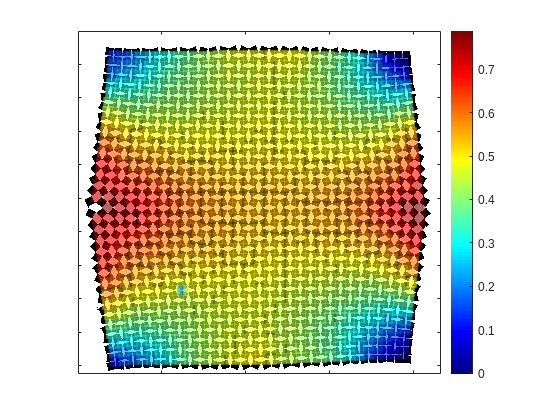

colormap jet;
scatter2.MarkerFaceAlpha = .6;
scatter2.Marker = 's';
set(gca,'XtickLabel',[],'YtickLabel',[])
colorbar